# ========================================================================

## ======================== CONFIGURATION =================================

clc; clear; close all;

% User profile (modify for each user)
userWeight = 70;    % kg
userHeight = 175;   % cm
userAge = 22;       % years
userName = 'Athlete';

fprintf('🏋 FitSense AI — Fitness Analytics Engine\n');

🏋 FitSense AI — Fitness Analytics Engine


fprintf('==========================================\n');

fprintf('User: %s | Weight: %dkg | Height: %dcm\n\n', userName, userWeight, userHeight);

User: Athlete | Weight: 70kg | Height: 175cm



## ============= SECTION 1: LOAD & INSPECT DATA ==========================

fprintf('📱 Section 1: Loading sensor data...\n');

📱 Section 1: Loading sensor data...



% Load the example data provided
load('ExampleData.mat');
load('ActivityLogs.mat');

% Display available variables
fprintf('  Available sensor data:\n');

  Available sensor data:


whos Acceleration Position

  Name                  Size             Bytes  Class        Attributes

  Acceleration      19418x3             622897  timetable              
  Position            217x6              14467  timetable              




% Preview the acceleration data
fprintf('\n  Acceleration data preview:\n');


  Acceleration data preview:


head(Acceleration)

           Timestamp                X          Y         Z   
    ________________________    _________    ______    ______

    06-Sep-2018 13:27:32.971       1.8902    5.1196    6.7059
    06-Sep-2018 13:27:32.990      0.54941    4.8946    7.0004
    06-Sep-2018 13:27:33.009     -0.56628    4.6576    7.7426
    06-Sep-2018 13:27:33.027     -0.74345    4.4971    9.1767
    06-Sep-2018 13:27:33.047      -0.1904    4.7533    9.7346
    06-Sep-2018 13:27:33.066    -0.097031    5.0215    9.4377
    06-Sep-2018 13:27:33.085      0.25493    4.7821    9.5909
    06-Sep-2018 13:27:33.104       0.3076    4.8323    9.6508



## ============= SECTION 2: DATA PREPROCESSING ===========================

fprintf('\n🔧 Section 2: Preprocessing sensor data...\n');


🔧 Section 2: Preprocessing sensor data...



% Apply signal processing pipeline
[accelClean, magClean, timeVec, Fs] = preprocessSensorData(Acceleration);

  Detected sampling frequency: 53 Hz
  Preprocessing complete. 19418 samples processed.


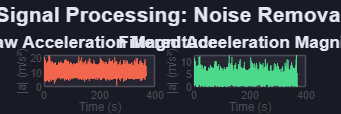


% === Visualization: Before vs After Filtering ===
figure('Color', [0.1 0.1 0.14], 'Position', [100 100 1200 400]);

subplot(1, 2, 1);
rawMag = sqrt(Acceleration{:,1}.^2 + Acceleration{:,2}.^2 + Acceleration{:,3}.^2);

rawTime = timeElapsed(Acceleration.Timestamp);
plot(rawTime, rawMag, 'Color', [0.95 0.4 0.3], 'LineWidth', 0.8);
title('Raw Acceleration Magnitude', 'Color', [0.9 0.9 0.95], 'FontSize', 13);
xlabel('Time (s)', 'Color', [0.9 0.9 0.95]);
ylabel('|a| (m/s²)', 'Color', [0.9 0.9 0.95]);
set(gca, 'Color', [0.15 0.15 0.2], 'XColor', [0.3 0.3 0.35], 'YColor', [0.3 0.3 0.35]);
grid on;

subplot(1, 2, 2);
plot(timeVec, magClean, 'Color', [0.3 0.85 0.55], 'LineWidth', 0.8);
title('Filtered Acceleration Magnitude', 'Color', [0.9 0.9 0.95], 'FontSize', 13);
xlabel('Time (s)', 'Color', [0.9 0.9 0.95]);
ylabel('|a| (m/s²)', 'Color', [0.9 0.9 0.95]);
set(gca, 'Color', [0.15 0.15 0.2], 'XColor', [0.3 0.3 0.35], 'YColor', [0.3 0.3 0.35]);
grid on;

sgtitle('Signal Processing: Noise Removal', 'Color', [0.9 0.9 0.95], ...
    'FontSize', 16, 'FontWeight', 'bold');

## ============= SECTION 3: FEATURE ENGINEERING ===========================

fprintf('\n📊 Section 3: Extracting features...\n');


📊 Section 3: Extracting features...



% Extract features using sliding windows
featureTable = extractFeatures(accelClean, magClean, Fs, 2, 0.5);

  Extracted 44 features from 365 windows



% Display feature summary
fprintf('  Feature matrix size: %d windows × %d features\n', ...
    height(featureTable), width(featureTable));

  Feature matrix size: 365 windows × 44 features


head(featureTable(:, 1:8))  % Show first 8 features

      X_mean      X_std     X_var     X_rms     X_p2p      X_skew     X_kurt    X_iqr 
    __________    ______    ______    ______    ______    ________    ______    ______

      -0.20886    1.5869    2.5183    1.5932     8.041    -0.10604    3.0141    2.2891
     0.0082917    2.1568    4.6516    2.1466    8.2447    -0.28558    2.0306    3.1169
      0.013183    2.2881    5.2356    2.2774    7.5569    -0.31622    1.7294    4.0397
     -0.042001    1.8827    3.5446    1.8743    7.1162    -0.25836    2.0144    3.1421
     -0.024586    1.6367    2.6788    1.6292    7.8101     0.11567     2.545    2.5415
      -0.01442    1.6332    2.6672    1.6255    7.8101    0.057995    2.9775    1.9079
    -0.0024464    1.4206     2.

## ============= SECTION 4: STEP DETECTION ================================

fprintf('\n👣 Section 4: Detecting steps...\n');


👣 Section 4: Detecting steps...



[numSteps, stepLocs, peakVals] = detectSteps(magClean, Fs);

  Detected 601 steps



% Calculate stride length from steps and distance
% If GPS is available, use it; otherwise estimate
strideLength = 0.75; % meters (average stride)
stepDistance = numSteps * strideLength;
fprintf('  Estimated distance from steps: %.0f m\n', stepDistance);

  Estimated distance from steps: 451 m


## ============= SECTION 5: GPS DISTANCE =================================

fprintf('\n🗺️ Section 5: Calculating GPS distance...\n');


🗺️ Section 5: Calculating GPS distance...


  GPS distance: 513 m


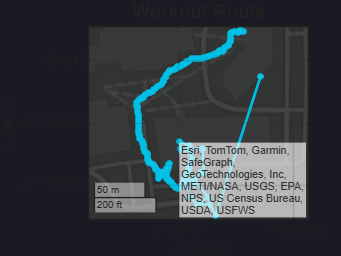


totalDistance = 0;
if exist('Position', 'var') && ~isempty(Position)
    try
        lat = Position.latitude;
        lon = Position.longitude;
        totalDistance = haversine(lat, lon);
        fprintf('  GPS distance: %.0f m\n', totalDistance);
        
        % GPS Route Visualization
        figure('Color', [0.1 0.1 0.14], 'Position', [100 100 800 600]);
        
        % If geoplot is available, use it
        try
            geoplot(lat, lon, '-o', 'Color', [0 0.75 0.9], ...
                'MarkerSize', 3, 'MarkerFaceColor', [0.3 0.85 0.55], ...
                'LineWidth', 2);
            geobasemap('streets-dark');
            title('Workout Route', 'FontSize', 14);
        catch
            % Fallback to regular plot
            plot(lon, lat, '-o', 'Color', [0 0.75 0.9], ...
                'MarkerSize', 4, 'MarkerFaceColor', [0.3 0.85 0.55], ...
                'LineWidth', 2);
            set(gca, 'Color', [0.15 0.15 0.2], 'XColor', [0.3 0.3 0.35], ...
                'YColor', [0.3 0.3 0.35]);
            xlabel('Longitude', 'Color', [0.9 0.9 0.95]);
            ylabel('Latitude', 'Color', [0.9 0.9 0.95]);
            title('Workout Route', 'Color', [0.9 0.9 0.95], 'FontSize', 14);
            grid on;
        end
    catch e
        fprintf('  GPS data not available or invalid: %s\n', e.message);
        totalDistance = stepDistance; % Fallback to step-based distance
    end
else
    fprintf('  No GPS data available. Using step-based distance.\n');
    totalDistance = stepDistance;
end

## ============= SECTION 6: ACTIVITY CLASSIFICATION ======================

% ---- 6A: Prepare Training Data from Activity Logs ----
fprintf('\n🧠 Section 6A: Preparing training data from activity logs...\n');

% Process the provided ActivityLogs data
% These contain labeled recordings: sitAcceleration, walkAcceleration, runAcceleration
trainingData = {};
trainingLabels = {};

if exist('sitAcceleration', 'var')
    [sitClean, ~, ~, ~] = preprocessSensorData(sitAcceleration);
    trainingData{end+1} = sitClean;
    trainingLabels{end+1} = 'sitting';
    fprintf('  Loaded sitting data: %d samples\n', size(sitClean, 1));
end

if exist('walkAcceleration', 'var')
    [walkClean, ~, ~, ~] = preprocessSensorData(walkAcceleration);
    trainingData{end+1} = walkClean;
    trainingLabels{end+1} = 'walking';
    fprintf('  Loaded walking data: %d samples\n', size(walkClean, 1));
end

if exist('runAcceleration', 'var')
    [runClean, ~, ~, ~] = preprocessSensorData(runAcceleration);
    trainingData{end+1} = runClean;
    trainingLabels{end+1} = 'running';
    fprintf('  Loaded running data: %d samples\n', size(runClean, 1));
end

% If you collected additional data, add it here:
% Example:
% load('jogging_data.mat');
% [jogClean, ~, ~, ~] = preprocessSensorData(joggingAcceleration);
% trainingData{end+1} = jogClean;
% trainingLabels{end+1} = 'jogging';

fprintf('  Total training classes: %d\n', length(trainingLabels));

% ---- 6B: Train LSTM Deep Learning Classifier ----
fprintf('\n🧠 Section 6B: Training LSTM Deep Learning Classifier...\n');

try
    [lstmNet, lstmAccuracy, YPred_LSTM, YTest_LSTM] = ...
        trainLSTMClassifier(trainingData, trainingLabels, Fs, 2);
    fprintf('  LSTM model trained successfully!\n');
    lstmTrained = true;
catch e
    fprintf('  LSTM training failed: %s\n', e.message);
    fprintf('  Continuing with classic ML only...\n');
    lstmAccuracy = 0;
    YPred_LSTM = [];
    YTest_LSTM = [];
    lstmTrained = false;
end

% ---- 6C: Train Classic ML Classifiers (for comparison) ----
fprintf('\n🧠 Section 6C: Training Classic ML Classifiers...\n');

% Extract features for each training recording and combine
allFeatures = [];
allLabels = {};

for i = 1:length(trainingData)
    data = trainingData{i};
    mag = sqrt(sum(data.^2, 2));
    ft = extractFeatures(data, mag, Fs, 2, 0.5);
    nWindows = height(ft);
    
    allFeatures = [allFeatures; ft];
    allLabels = [allLabels; repmat(trainingLabels(i), nWindows, 1)];
end

try
    [bestClassicModel, bestClassicName, classicResults] = ...
        trainClassicML(allFeatures, allLabels);
    classicTrained = true;
catch e
    fprintf('  Classic ML training failed: %s\n', e.message);
    classicResults = table({'Baseline'}, {0}, 'VariableNames', {'Model', 'Accuracy_Pct'});
    classicTrained = false;
end

% ---- 6D: Classify the test workout ----
fprintf('\n🏃 Section 6D: Classifying test workout...\n');

% Use LSTM if available, otherwise use classic ML
testFeatures = extractFeatures(accelClean, magClean, Fs, 2, 0.5);
nTestWindows = height(testFeatures);

if lstmTrained
    % Prepare sequences for LSTM
    windowSize = round(2 * Fs);
    stepSize = round(windowSize * 0.5);
    nSamples = size(accelClean, 1);
    testSequences = {};
    
    mag4lstm = sqrt(sum(accelClean.^2, 2));
    data4ch = [accelClean, mag4lstm];
    
    for startIdx = 1:stepSize:(nSamples - windowSize + 1)
        endIdx = startIdx + windowSize - 1;
        window = data4ch(startIdx:endIdx, :)';
        testSequences{end+1} = window;
    end
    
    if ~isempty(testSequences)
        activityPredictions = classify(lstmNet, testSequences);
        fprintf('  Classified %d windows using LSTM\n', length(activityPredictions));
    else
        activityPredictions = categorical({'unknown'});
    end
elseif classicTrained
    testArray = table2array(testFeatures);
    testArray(isnan(testArray)) = 0;
    testArray(isinf(testArray)) = 0;
    activityPredictions = predict(bestClassicModel, testArray);
    if ~iscategorical(activityPredictions)
        activityPredictions = categorical(activityPredictions);
    end
    fprintf('  Classified %d windows using %s\n', length(activityPredictions), bestClassicName);
else
    activityPredictions = repmat(categorical({'walking'}), nTestWindows, 1);
end

## ============= SECTION 7: CALORIE ESTIMATION ============================

fprintf('\n🔥 Section 7: Calculating calories...\n');

windowDuration = 2; % seconds per window
windowDurations = repmat(windowDuration, length(activityPredictions), 1);

[totalCalories, calorieTimeline, metValues] = ...
    calculateCalories(cellstr(activityPredictions), windowDurations, userWeight);

## ============= SECTION 8: VISUALIZATION DASHBOARD =======================

fprintf('\n📊 Section 8: Generating visualizations...\n');

% 8A: Main 6-panel dashboard
plotFitnessDashboard(timeVec, accelClean, magClean, stepLocs, ...
    activityPredictions, calorieTimeline, totalCalories, numSteps, totalDistance, Fs);

% 8B: Model comparison
if lstmTrained || classicTrained
    plotModelComparison(lstmAccuracy, classicResults, YPred_LSTM, YTest_LSTM);
end

% 8C: Workout DNA fingerprint
createWorkoutDNA(activityPredictions, magClean, numSteps, totalCalories, totalDistance, Fs);

% 8D: 3D Acceleration Trajectory
figure('Color', [0.1 0.1 0.14], 'Position', [100 100 700 600]);
plot3(accelClean(:,1), accelClean(:,2), accelClean(:,3), ...
    'Color', [0 0.75 0.9 0.3], 'LineWidth', 0.5);
hold on;
scatter3(accelClean(1,1), accelClean(1,2), accelClean(1,3), 100, ...
    [0.3 0.85 0.55], 'filled', 'MarkerEdgeColor', 'w');
scatter3(accelClean(end,1), accelClean(end,2), accelClean(end,3), 100, ...
    [0.95 0.4 0.3], 'filled', 'MarkerEdgeColor', 'w');
hold off;
xlabel('X Acceleration', 'Color', [0.9 0.9 0.95]);
ylabel('Y Acceleration', 'Color', [0.9 0.9 0.95]);
zlabel('Z Acceleration', 'Color', [0.9 0.9 0.95]);
title('3D Acceleration Trajectory', 'Color', [0.9 0.9 0.95], 'FontSize', 14);
legend({'Trajectory', 'Start', 'End'}, 'TextColor', [0.9 0.9 0.95], ...
    'Color', [0.15 0.15 0.2], 'EdgeColor', [0.3 0.3 0.35]);
set(gca, 'Color', [0.15 0.15 0.2], 'XColor', [0.3 0.3 0.35], ...
    'YColor', [0.3 0.3 0.35], 'ZColor', [0.3 0.3 0.35]);
grid on;
view(45, 30);

## ============= SECTION 9: FINAL SUMMARY =================================

fprintf('\n');
fprintf('==========================================\n');
fprintf('🏆 FitSense AI — Workout Summary\n');
fprintf('==========================================\n');
fprintf('👤 User:       %s (%d kg, %d cm, %d years)\n', userName, userWeight, userHeight, userAge);
fprintf('👣 Steps:      %d\n', numSteps);
fprintf('📏 Distance:   %.0f meters (%.2f km)\n', totalDistance, totalDistance/1000);
fprintf('🔥 Calories:   %.1f kcal\n', totalCalories);
fprintf('⏱️  Duration:   %.1f minutes\n', timeVec(end)/60);

if totalDistance > 0
    avgPace = (timeVec(end)/60) / (totalDistance/1000);
    avgSpeed = (totalDistance/1000) / (timeVec(end)/3600);
    fprintf('🏃 Avg Speed:  %.1f km/h\n', avgSpeed);
    fprintf('🏃 Avg Pace:   %.1f min/km\n', avgPace);
end

fprintf('\n🍌 That''s %.1f bananas burned!\n', totalCalories/105);
fprintf('🍕 Or %.1f slices of pizza!\n', totalCalories/285);

if lstmTrained
    fprintf('\n🧠 LSTM Accuracy: %.1f%%\n', lstmAccuracy);
end
if classicTrained
    fprintf('📊 Best Classic ML: %s\n', bestClassicName);
end

fprintf('\n✅ FitSense AI analysis complete!\n');
fprintf('==========================================\n');